%ともかく、固有ベクトルは出ているものする
%固有振動数も出ている
Mesured_points_num=3;
Mesured_modes_num=3;
mode_degree=[]%上の各モードについて、一般には1,2,3と取っていくが、シェルはそうでもないので一応用意、其々のモードの次数を入れる


mode_degree =

     []



mode_shapes=[1,0.7,0.15;
             0.2,-0.6,-0.7;
             -0.15,0.9,-1]'%各モードについて、（各点の振幅という意味で）固有ベクトルをいれていく

mode_shapes =     1.0000    0.2000   -0.1500
    0.7000   -0.6000    0.9000
    0.1500   -0.7000   -1.0000


%列がモード行が点
f=[20,0,0;
    0,50,0;
    0,0,100]*2*pi;
color=["red","blue","green"]

color = 1×3 の string 配列
    "red"    "blue"    "green"


for i=1:1:3
    hold on
    plot([mode_shapes(:,i);0],"--","LineWidth",2,"Color",color(i))
   
end
%修論メソッドでは、ともかくまずMを計算する
mass=return_M(mode_shapes);
%モードと測定点は同じ数の方がよさそう
%修正行列N×M行列で、其々のpq要素には、p,qのための修正項がはいる（Nずつ、２N）これを後で加える？
diff_p=0;diff_q=0

diff_q = 0

mass

mass =     1.0625    0.4450    0.1600
    0.4450    1.6600   -0.3750
    0.1600   -0.3750    1.5125


diffsp=zeros(Mesured_points_num);
diffsq=zeros(Mesured_points_num);
while eps_asym(mass)>10^-6
for p=1:1:Mesured_points_num
    for q=1:1:Mesured_points_num
        if p~=q
        %mass(p,q)
        %Mass p,qについてepsを消すために調製する
        %diff_p=mode_shapes(:,q);diff_p=(diff_p')/(diff_p'*diff_p)*(-mass(p,q));
        %diff_q=mode_shapes(:,p);diff_p=(diff_q')/(diff_q'*diff_q)*(-mass(p,q));
        diff_p=mode_shapes(q,:)*(-mass(p,q))*0.1;
        diff_q=mode_shapes(p,:)*(-mass(p,q))*0.1;
        mode_shapes(p,:)=mode_shapes(p,:)+diff_p;
        mode_shapes(q,:)=mode_shapes(q,:)+diff_q;
        %diffsp(:,p)=diffsp(:,p)-mass(p,q)*mode_shapes(:,q)*0.5;
        %diffsq(:,q)=diffsq(:,q)-mass(p,q)*mode_shapes(:,p)*0.5;
        end
    end
end
    %mode_shapes(:,:)=mode_shapes(:,:)+diff_p+diff_q;
    mass=return_M(mode_shapes);
end
mass

mass =     0.9581    0.0000    0.0000
    0.0000    1.5131   -0.0000
    0.0000   -0.0000    1.4355


mode_shapes

mode_shapes =     0.8690    0.3909   -0.2238
    0.5458   -0.7516    0.8064
    0.1463   -0.8189   -0.8623


k=(mode_shapes')^-1*(f.^2)*(mode_shapes)^-1

k = 	1.0e+05 *

    0.5097   -0.6399    0.3388
   -0.6399    1.3853   -0.9784
    0.3388   -0.9784    1.7473




mode_shapes'*mass*mode_shapes

ans =     1.2050   -0.4673    0.2986
   -0.4673    1.9638    0.0126
    0.2986    0.0126    2.0992


mode_shapes'*k*mode_shapes

ans = 	1.0e+05 *

    0.1579   -0.0000    0.0000
    0.0000    0.9870   -0.0000
    0.0000         0    3.9478




%%%
%ここから、ともかくモードについて、どこか一点で質量を代表させてそれで正規化する
deleg_point=[1,2,2]%最大値を多分とる（あとでやるわ）

deleg_point =      1     2     2



for mode=1:1:Mesured_modes_num
    normX=mode_shapes(:,mode)./mode_shapes(deleg_point(mode),mode);
    delegate_M=normX'*mass*normX
    mode_shapes(:,mode)=mode_shapes(:,mode)/delegate_M;
end

delegate_M = 1.5957

delegate_M = 3.4762

delegate_M = 3.2281

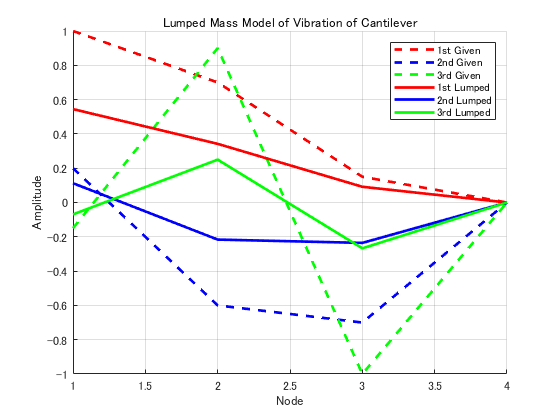

%列がモード行が点
for i=1:1:3
    hold on
    plot([mode_shapes(:,i);0],"-","LineWidth",2,"Color",color(i))
   
end
title("Lumped Mass Model of Vibration of Cantilever")
xlabel("Node")
xlim([1,4])
ylabel("Amplitude")
legend("1st Given","2nd Given","3rd Given","1st Lumped","2nd Lumped","3rd Lumped")
grid on

function mass=return_M(mode_shapes)
    mass=mode_shapes*mode_shapes';
end 
function eps=eps_asym(mass)
    eps=0;
    N=3;M=3;
    for i=1:1:N
        for j=1:1:M
            if i~=j
                eps=eps+abs(mass(i,j));
            end
        end
    end
end